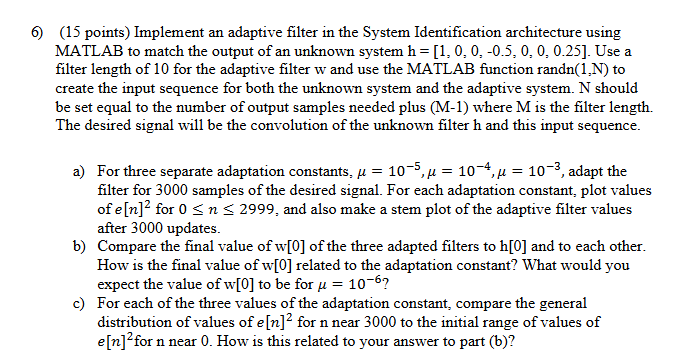

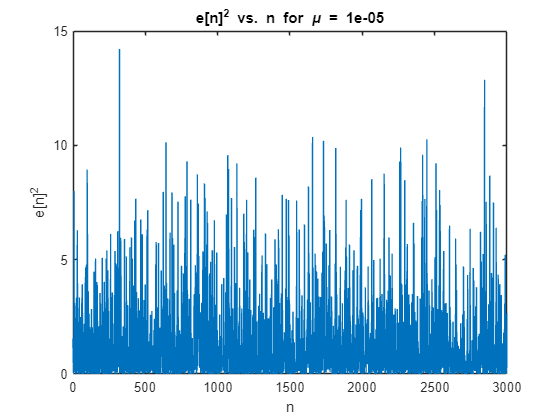

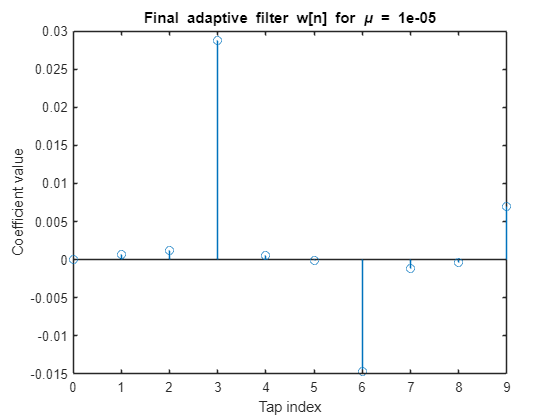

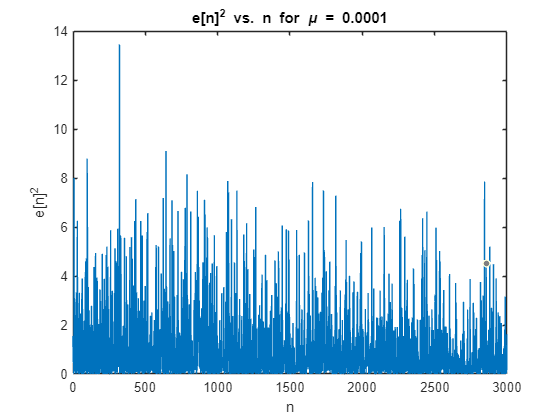

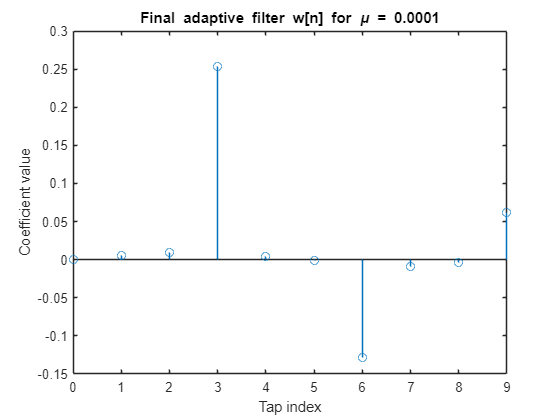

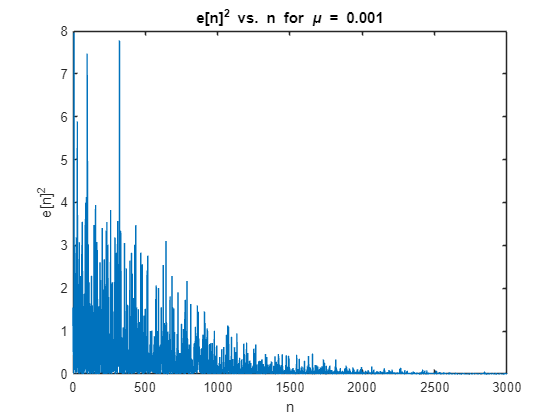

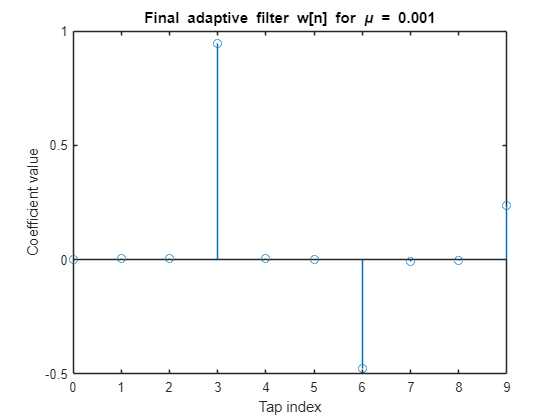


h = [1, 0, 0, -0.5, 0, 0, .25];  
M = 10;                           
mu_vals = [1e-5, 1e-4, 1e-3];     
N = 3000 + M - 1;                 

x = randn(1, N);

d = conv(x, h, 'valid');  % length = 3000

for k = 1:length(mu_vals)
    mu = mu_vals(k);
    
    w = zeros(M, 1); % adaptive filter
    e = zeros(1, 3000); % error 
    y = zeros(1, 3000); % output

    
    for n = 1:3000
        x_n = x(n+M-1:-1:n).';    
        y(n) = w' * x_n;          
        e(n) = d(n) - y(n);       
        w = w + mu * x_n * e(n);  
    end

    % plot error squared
    figure;
    plot(0:2999, e.^2);
    title(['e[n]^2 vs. n for \mu = ', num2str(mu)]);
    xlabel('n'); 
    ylabel('e[n]^2');

    % stem plot of final filter coefficients
    figure;
    stem(0:M-1, w);
    title(['Final adaptive filter w[n] for \mu = ', num2str(mu)]);
    xlabel('Tap index'); 
    ylabel('Coefficient value');
end

mu=.001 gives us the closest w[0] value as it's almost 1, while the others are ~.25 and ~.03. A higher mu leads to better adapting. I would expect w[0] to be even lower for mu = 1e-6.

We also see as mu increases, the error function drops off way more. It's really only visible for mu=.001.

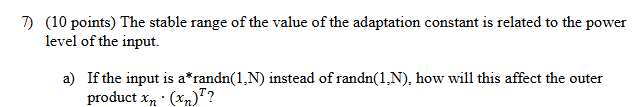

The outer product is now axn * (axn)^T = a^2 * (xn * (xn)^T)

It gets scaled by a^2.

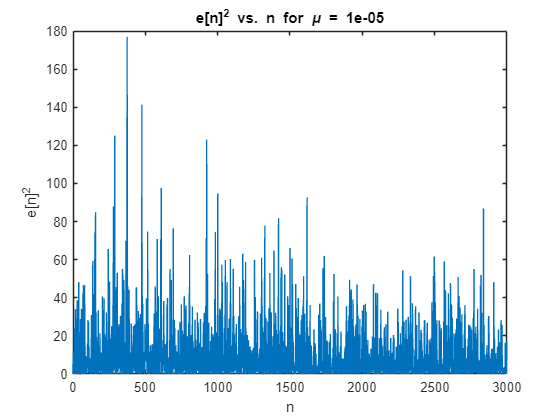

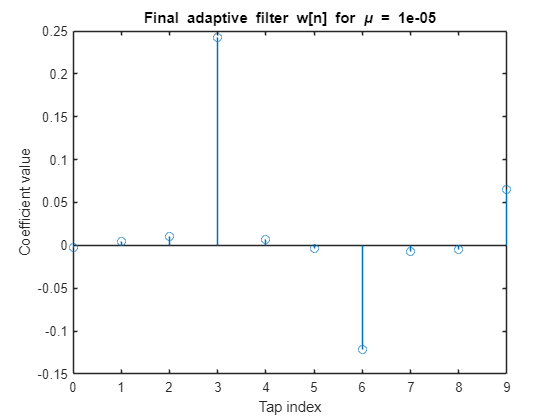

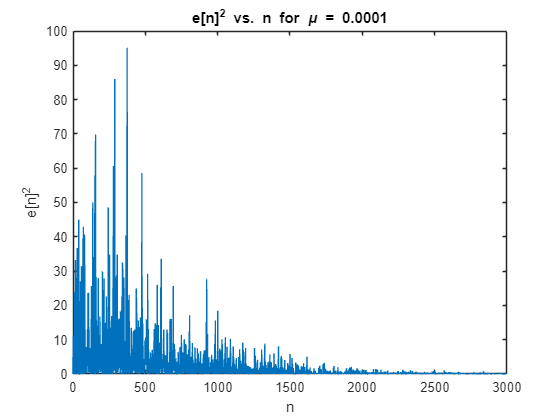

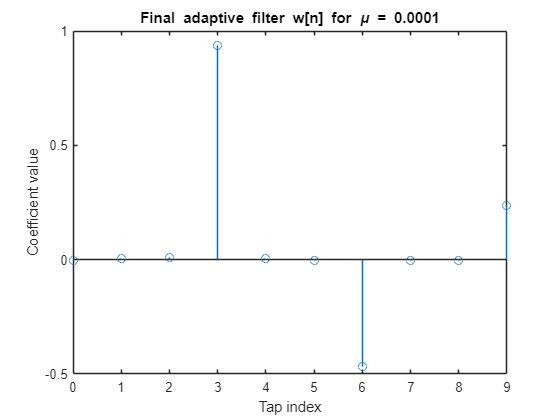

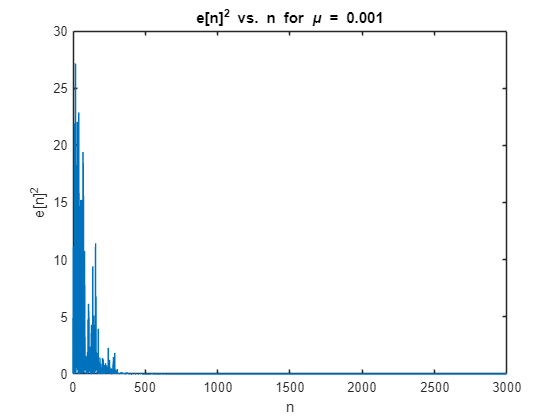

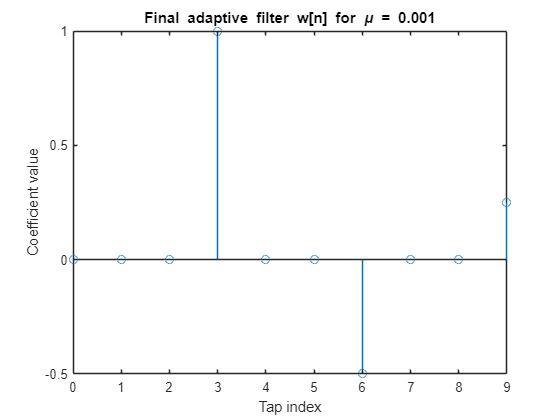

h = [1, 0, 0, -0.5, 0, 0, .25];  
M = 10;                           
mu_vals = [1e-5, 1e-4, 1e-3];     
N = 3000 + M - 1;                 
a = sqrt(10);

x = a*randn(1, N);

d = conv(x, h, 'valid');  % length = 3000

for k = 1:length(mu_vals)
    mu = mu_vals(k);
    
    w = zeros(M, 1); % adaptive filter
    e = zeros(1, 3000); % error 
    y = zeros(1, 3000); % output

    
    for n = 1:3000
        x_n = x(n+M-1:-1:n).';    
        y(n) = w' * x_n;          
        e(n) = d(n) - y(n);       
        w = w + mu * x_n * e(n);  
    end

    % plot error squared
    figure;
    plot(0:2999, e.^2);
    title(['e[n]^2 vs. n for \mu = ', num2str(mu)]);
    xlabel('n'); 
    ylabel('e[n]^2');

    % stem plot of final filter coefficients
    figure;
    stem(0:M-1, w);
    title(['Final adaptive filter w[n] for \mu = ', num2str(mu)]);
    xlabel('Tap index'); 
    ylabel('Coefficient value');
end

a helped the smaller mu values achieve more accurate weights and decrease the error function more rapidly. I presume the bigger the adaptation constant, the more accurate our weights can be.

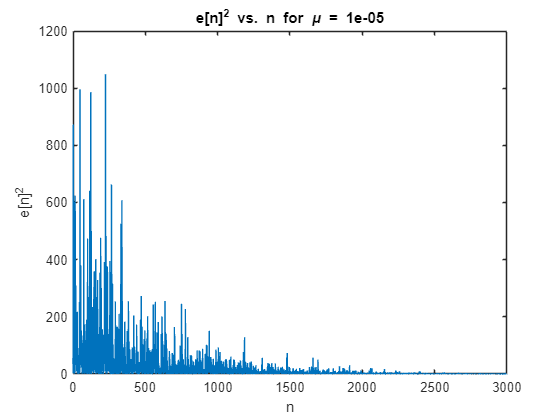

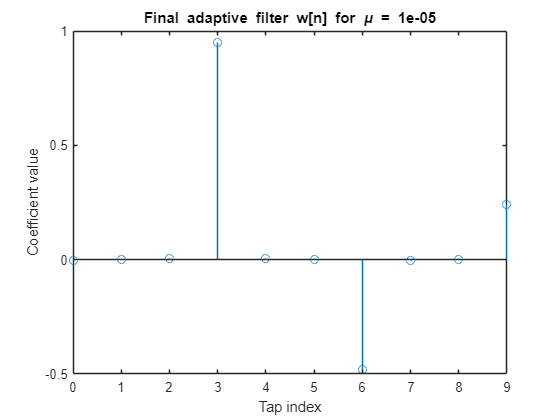

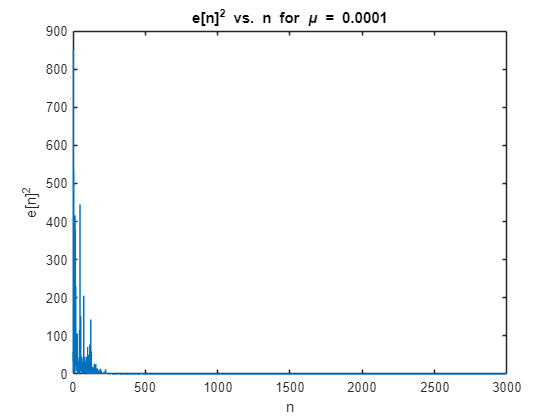

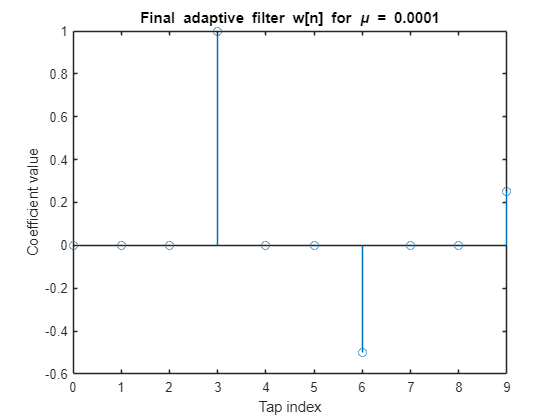

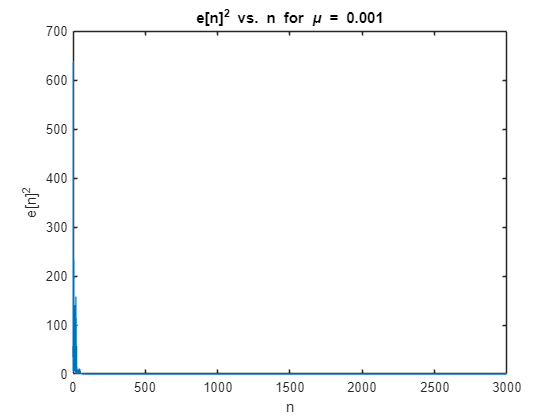

h = [1, 0, 0, -0.5, 0, 0, .25];  
M = 10;                           
mu_vals = [1e-5, 1e-4, 1e-3];     
N = 3000 + M - 1;                 
a = 10;

x = a*randn(1, N);

d = conv(x, h, 'valid');  % length = 3000

for k = 1:length(mu_vals)
    mu = mu_vals(k);
    
    w = zeros(M, 1); % adaptive filter
    e = zeros(1, 3000); % error 
    y = zeros(1, 3000); % output

    
    for n = 1:3000
        x_n = x(n+M-1:-1:n).';    
        y(n) = w' * x_n;          
        e(n) = d(n) - y(n);       
        w = w + mu * x_n * e(n);  
    end

    % plot error squared
    figure;
    plot(0:2999, e.^2);
    title(['e[n]^2 vs. n for \mu = ', num2str(mu)]);
    xlabel('n'); 
    ylabel('e[n]^2');

    % stem plot of final filter coefficients
    figure;
    stem(0:M-1, w);
    title(['Final adaptive filter w[n] for \mu = ', num2str(mu)]);
    xlabel('Tap index'); 
    ylabel('Coefficient value');
end

As predicted, the higher adaptation constant led to more accurate weights and a much quicker dropoff on the error function output for all mus.